Rainflow counting inability hypothesis testing

close all
smin = [0 0 0 0 0 0 0 0]';
smax1 = [4 3 2 1 4 3 2 1]';
smax2 = [4 1 2 3 4 1 2 3]';
repetition = 1;
x1 = pv2revs(smax1, smin);
x2 = pv2revs(smax2, smin);
x1 = [repmat(x1(:,2),repetition,1); 0];
x2 = [repmat(x2(:,2),repetition,1); 0];
% Rainflow counting of the above two stress reversals
RF1 = rainflow(x1);
RF2 = rainflow(x2);

figure(1),clf
subplot(211)
plot(x1),hold on, plot(x2),pbaspect([2 1 1])
subplot(212)
plot(sort(RF1(:,2))), hold on, plot(sort(RF2(:,2))),pbaspect([2 1 1])

figure(2),clf
subplot(121)
h1 = histogram2(RF1(:,2),RF1(:,3));
h1.FaceColor = 'flat';
h1.EdgeColor = 'none';
subplot(122)
h2 = histogram2(RF2(:,2),RF2(:,3));
h2.FaceColor = 'flat';
h2.EdgeColor = 'none';

Now, try a more randomized maximum stress reverals. 1. designate the largest stress cycle, $\sigma_\max^\max = \max(\sigma_{\max})$; 2. all the rest maximum stresses are less than the largest stress cycle, say, in total $N$maximum stresses; 3. based on the current history, randomly permute the last $N-1$ maximum stresses and create a new maximum stress history. Make these two maximum stress histories into two reversals and make them periodic.

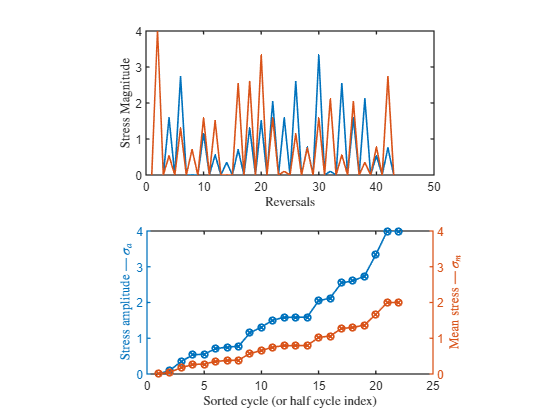

close all
AR = [2 1 1];
smaxm = 4;
smin0 = 0;
rng(1);
smaxrand1 = 3.8*rand(1,20);
smaxrand2 = smaxrand1(randperm(length(smaxrand1)));
smax1 = [smaxm smaxrand1]';
smax2 = [smaxm smaxrand2]';
smin = zeros(length(smax1),1);
repetition = 1;
x1 = pv2revs(smax1, smin);
x2 = pv2revs(smax2, smin);
x1 = [repmat(x1(:,2),repetition,1); 0];
x2 = [repmat(x2(:,2),repetition,1); 0];
% Rainflow counting of the above two stress reversals
RF1 = rainflow(x1);
RF2 = rainflow(x2);

% -------------------- Run OL identifier --------------------------------
Omega1 = OLSpectrum(x1, 'True');
Omega2 = OLSpectrum(x2, 'True');
% -----------------------------------------------------------------------

% -------------------- Run OL sifter ------------------------------------
OLI1 = OLIndex(Omega1, 1);
OLI2 = OLIndex(Omega2, 1);
% -----------------------------------------------------------------------
figure(3),clf
subplot(211)
plot(x1),hold on, plot(x2),pbaspect(AR)
xlabel('Reversals')
ylabel('Stress Magnitude')
subplot(212)
yyaxis left
plot(sort(RF1(:,2)),'-o'), hold on, plot(sort(RF2(:,2)),'-x'),pbaspect(AR)
xlabel('Sorted cycle (or half cycle index)')
ylabel('Stress amplitude --- $\sigma_a$')
yyaxis right
plot(sort(RF1(:,3)),'-o'), hold on, plot(sort(RF2(:,3)),'-x'),pbaspect(AR)
ylabel('Mean stress --- $\sigma_m$')
ylim([0 smaxm])

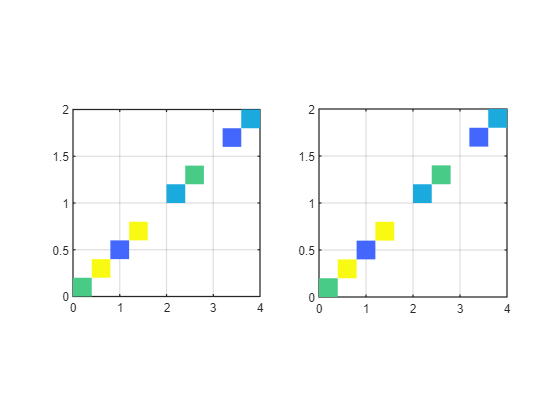


figure(4),clf
subplot(121)
h1 = histogram2(RF1(:,2),RF1(:,3),10);
h1.FaceColor = 'flat';
h1.EdgeColor = 'none';
view(0, 90)
pbaspect([1 1 1])
subplot(122)
h2 = histogram2(RF2(:,2),RF2(:,3),10);
h2.FaceColor = 'flat';
h2.EdgeColor = 'none';
view(0, 90)
pbaspect([1 1 1])

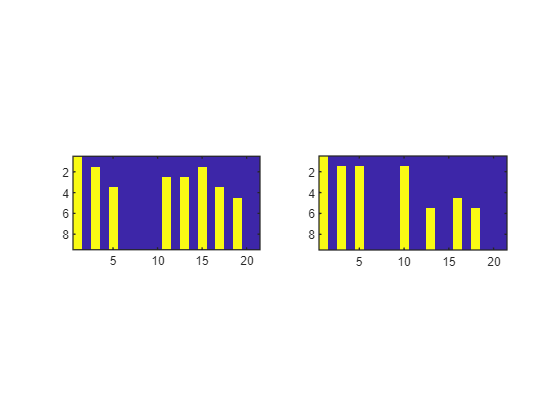


figure(3),clf
subplot(121)
imagesc(OLI1)
pbaspect([2 1 1])
subplot(122)
imagesc(OLI2)
pbaspect([2 1 1])